# Sistemas Realimentados - 2023/1

## Nome: coloque seu nome aqui

## Data de entrega limite: 4/4

## Trabalho 1 

**Referências para ler para este trabalho**

- [Manual rápido do Matlab](https://drive.google.com/file/d/1_mXyft7ynFmkxGnCyx7BV8VyOKyIx9tj/view?usp=share_link)

- [Resposta transitória e estacionária](https://drive.google.com/file/d/19GToHEkcvTon0UK2nOmi1_l0k5dx3YIJ/view?usp=share_link)

## Resposta transitória e de regime de sistemas dinâmicos

Definições:

datetime('now')
I=0;
[tau,zeta,wn,teta,p] = init(I);
g1=tf(p,[tau 1]);
g2=tf(wn^2,[1 2*zeta*wn wn^2]);
g0=tf(p,[tau 1],'InputDelay',teta);
g3=tf(p^3,poly(-[p p p]));
[y0,t0]=step(g0);
[y1,t1]=step(g1);
[y2,t2]=step(g2);


1) Obtenha a constante de tempo, o tempo de estabilização e o ganho do sistema cuja resposta ao degrau unitário é mostrada na figura 1.

figure;
plot(t1,y1);legend('Tempo(s)');title('Figura 1');

Resposta:

2) Obtenha a constante de tempo, o tempo morto, o tempo de estabilização e o ganho do sistema cuja resposta degrau unitário é mostrada na figura 2.

figure;
plot(t0,y0);legend('Tempo(s)');title('Figura 2');

Resposta:

3) Obtenha o tempo de subida, a sobre-elevação (0 a 100%), o tempo de estabilização, o ganho do sistema cuja resposta ao degrau unitário é mostrada na figura 3.

figure;
plot(t2,y2);legend('Tempo(s)');title('Figura 3');

Resposta:

4) Na figura 4  mostra-se o efeito do amortecimento $\zeta$na sobreelevação (UP) e tempo de estabilização (ts).  A relação UP com $\zeta$ é dada por $\textrm{UP}=100e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$, e a relação de ts com $\zeta$é dada aproximadamente por $\textrm{ts}=\frac{4}{\zeta \omega_n }$, $0<\zeta <0\ldotp 9$.

z=linspace(0.1,0.7,50);
ts=[];UP=[];
for i=1:50
    m=tf(wn^2,[1 2*z(i)*wn wn^2]);
    S=stepinfo(m);
    ts(i,1)=S.SettlingTime;
    UP(i,1)=S.Overshoot;
end
figure;
subplot(211);plot(z,UP);xlabel('\zeta');ylabel('UP');title('Figura 4')
subplot(212);plot(z,ts);xlabel('\zeta');ylabel('ts')

Explique, observando as figuras, como $\zeta$se relaciona com UP e ts, e obtenha a faixa de valores de $\zeta$para os quais a sobre-elevação esteja entre 40 e 50%, verificando a que faixa de valores de tempo de estabelecimento isso corresponde.

Resposta:

Seja a localização do par de polos complexos de uma FT de um protótipo de segunda ordem mostrada na figura 5.

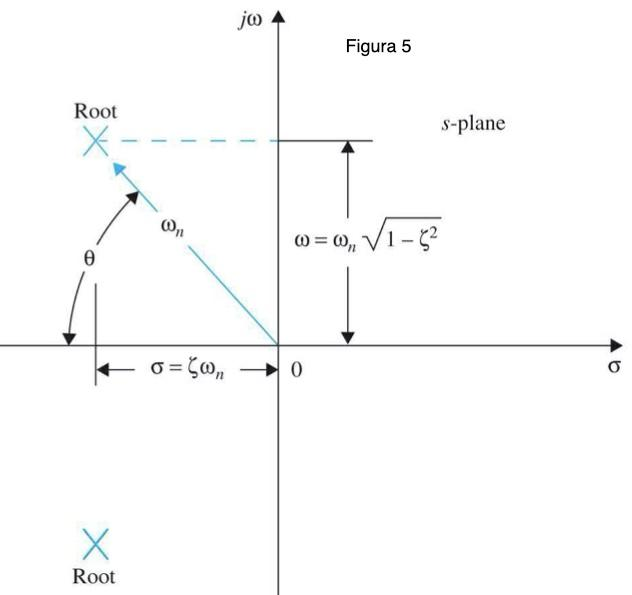

5) Use a expressão que relaciona de ts com $\zeta$e $\omega_n$ para explicar onde devem estar os polos de malha fechada para um menor tempo de estabilização. 

Resposta:

6) Sabendo que $\zeta =\cos \left(\theta \right)$, em que região do plano complexo devem estar os polos para que UP seja menor que 5%?

Resposta:

7) A figura 6 mostra a resposta ao impulso do sistema de segunda ordem do item 3. Explique como obter a resposta ao impulso a partir de G(s) usando a transformada de Laplace.

figure;impulse(g2);title('Figura 6')

8) Observe a resposta ao degrau do item 3) e escolha um tempo de amostragem de 10% do valor do tempo de estabilização medido. Discretize o modelo g2 usado com o comando c2d e plote no mesmo gráfico a resposta ao degrau dos sistemas contínuo e discreto.

 % Coloque aqui os comandos para discretizar g2 e plotar respostas 
figure

title('Figura 7')

Seja o sistema massa-mola-amortecedor mostrado na figura 7 e a equação diferencial que gere seu comportamento. $X$é o deslocamento em metros e $F$a força aplicada em Newtons.


$$m\ddot{x}+b\dot{x}+kx=f(t)$$


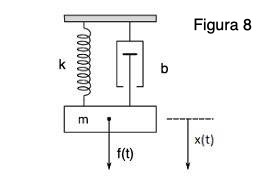

7) Obtenha a função de transferência $G\left(s\right)=\frac{X\left(s\right)}{F\left(s\right)}$ e faça sua simulação ao degrau com os parâmetros M,K,B definidos abaixo. Qual o deslocamento máximo da massa e qual seu tempo de estabelecimento?

Resposta:

M=I;
K=M*sqrt(wn);
B=2*M*zeta*wn;
figure
title('Figura 9');

8) Seja o diagrama de blocos mostrado abaixo.

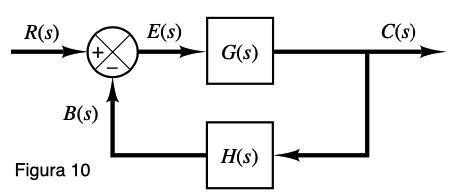

Obtenha:


$$\frac{E\left(s\right)}{R\left(s\right)}$$



$$\frac{C\left(s\right)}{R\left(s\right)}$$


9) Seja o sistema massa-mola-amortecedo do item 7. Obtenha o modelo em variáveis de estado definido pelas matrizes [A,B,C,D] de modo que $x_1 \left(t\right)$ seja a posição e $x_2 \left(t\right)$seja a velocidade. Aplique então um degrau e plote os dois estados, explicando seu comportamento. Dica: veja o comando tf2ss.

figure
title('Figura 11')

10) Seja gma definida abaixo.

gma=tf(wn^2*[1/p 1],[1 2*zeta*wn 0]);

Obtenha seus polos e zeros de malha aberta e de malha fechada.

Resposta:

Análise do erro em regime. Seja o diagrama de blocos mostrado abaixo com G(s) definida abaixo.

G=tf(p^2,poly(-[p p]));

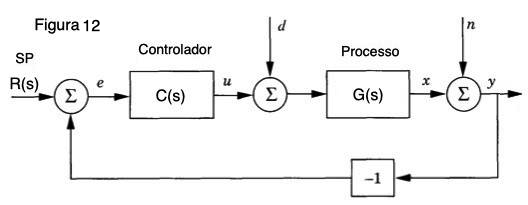

11. Qual o erro em regime para uma entrada degrau unitário caso $C\left(s\right)=K$?

Resposta:

12. Repita o item 11 para $C\left(s\right)=K_p +\frac{K_I }{s}$

Resposta:

13. Caso um distúrbio $d\left(t\right)=1$ afete a malha de controle, como verificar seu efeito no erro E(s) para um dado controlador C(s)?

Ilustre aplicando o degrau em $d\left(t\right)=1$e plotando $y(t)$, com $r(t)=0$. Use $C(s)=K$, onde K garante estabilidade.

figure


Resposta:

14. Verifique os valores de K para estabilidade de $\frac{Y(s)}{R(s)}=\frac{KG_3(s)}{1+KG_3(s)$ (g3 foi definida em init).

Resposta: